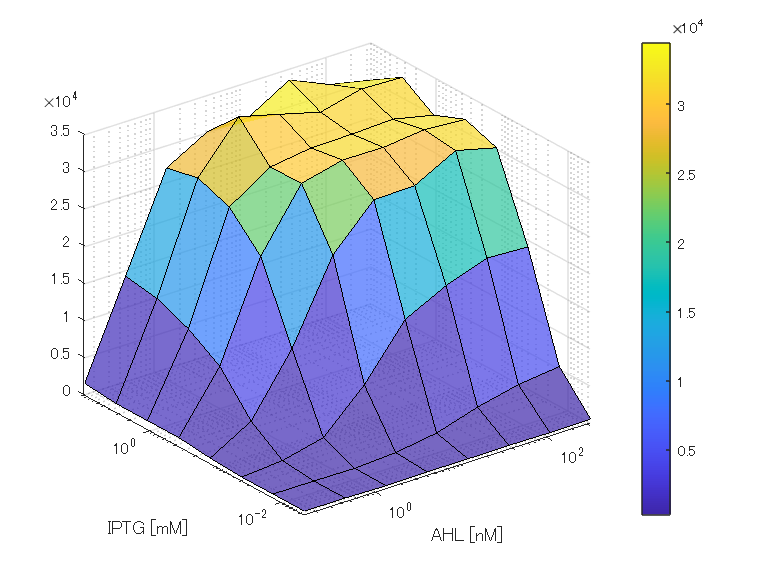

data = readmatrix("TA2946Data.xlsx");
IPTG = data(1,2:end)';
AHL = data(2:end,1);
[X,Y] = meshgrid(AHL,IPTG);
Z = data(2:end,2:end)';
surf(X,Y,Z,"FaceAlpha",0.7)
colorbar
set(gca,'XScale','log','YScale','log')
xlabel('AHL [nM]')
ylabel('IPTG [mM]')

k = 1;
AHLVar = zeros(64,1);
IPTGVar = zeros(64,1);
fluorVar = zeros(64,1);
for i = 1:8
    for j = 1:8
        fluorVar(k,1) = Z(i,j);
        AHLVar(k,1) = AHL(i);
        IPTGVar(k,1) = IPTG(j);
        k = k + 1;
    end
end
sf = fit([AHLVar,IPTGVar],fluorVar,'poly23')

     線形モデル Poly23:
     sf(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p21*x^2*y 
                    + p12*x*y^2 + p03*y^3
     係数 (95% の信頼限界):
       p00 =        4318  (-442.3, 9079)
       p10 =       235.4  (107.6, 363.1)
       p01 =   2.093e+04  (8024, 3.384e+04)
       p20 =     -0.5873  (-0.9658, -0.2088)
       p11 =        7.64  (-39.63, 54.91)
       p02 =       -6835  (-1.188e+04, -1790)
       p21 =    -0.01099  (-0.1119, 0.08994)
       p12 =     -0.4071  (-3.771, 2.957)
       p03 =       486.2  (103.2, 869.1)



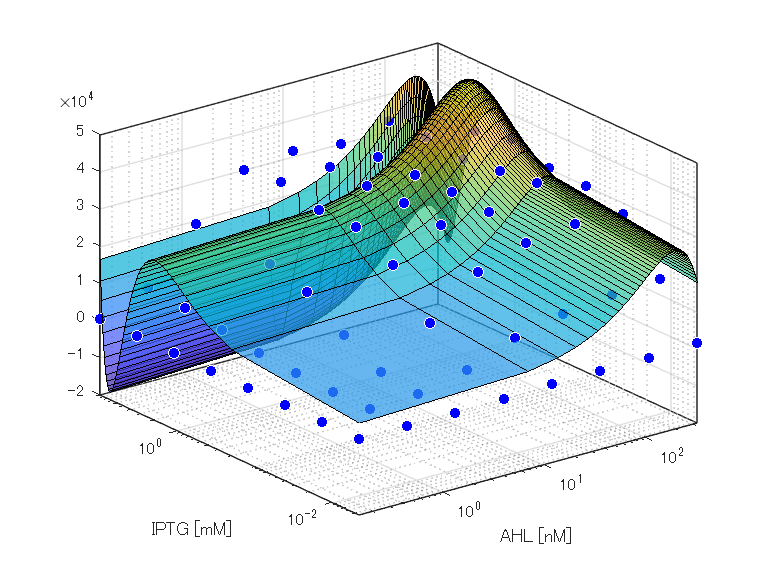

plot(sf,[AHLVar,IPTGVar],fluorVar)
set(gca,'XScale','log','YScale','log')
xlabel('AHL [nM]')
ylabel('IPTG [mM]')
alpha(0.7)

MM = @(fluorMax, K_AHL, K_IPTG, n1, n2, x, y) ...
    fluorMax*(x.^n1./(x.^n1 + K_AHL.^n1)).*(y.^n2./(y.^n2 + K_IPTG.^n2));


sf2 = fit([AHLVar,IPTGVar],fluorVar,MM,'StartPoint',[30000,1,1,1,1],'Lower',[0,0,0,1,1])

     一般モデル:
     sf2(x,y) = fluorMax*(x.^n1./(x.^n1+K_AHL.^n1)).*(y.^n2./(y.^n2+K_IPTG.^n2))
     係数 (95% の信頼限界):
       fluorMax =   3.261e+04  (3.12e+04, 3.402e+04)
       K_AHL =       1.596  (1.353, 1.839)
       K_IPTG =     0.02268  (0.01883, 0.02654)
       n1 =       1.752  (1.337, 2.168)
       n2 =       1.597  (1.226, 1.968)



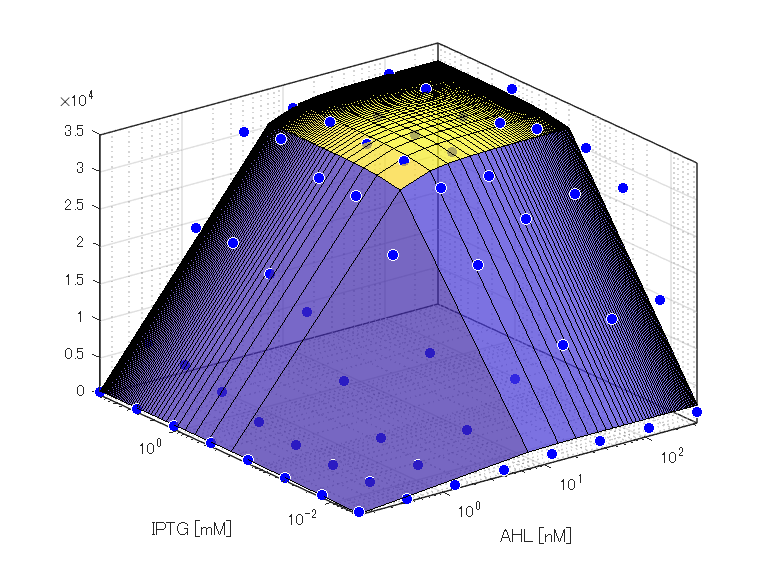

plot(sf2,[AHLVar,IPTGVar],fluorVar)
set(gca,'XScale','log','YScale','log')
xlabel('AHL [nM]')
ylabel('IPTG [mM]')
alpha(0.7)

fluorMax = 3.261e+04;
K_AHL = 1.596;
K_IPTG = 0.02268;
n1 = 1.752;
n2 = 1.597;

MMestimated = @(x,y) MM(fluorMax, K_AHL, K_IPTG, n1, n2, x, y)

MMestimated = 値をもつ function_handle :
    @(x,y)MM(fluorMax,K_AHL,K_IPTG,n1,n2,x,y)


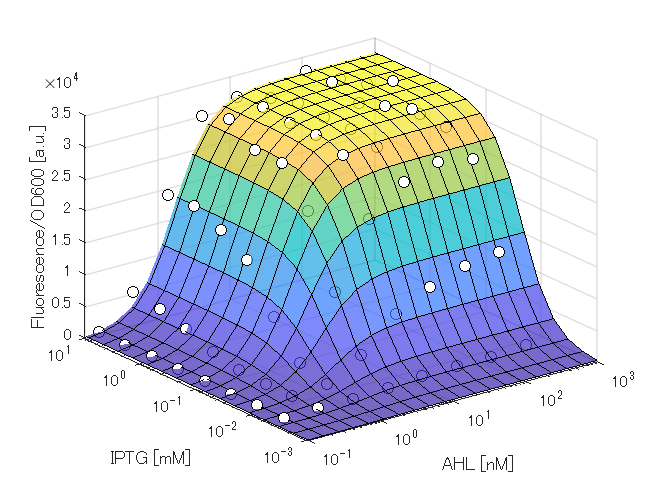

IPTG = logspace(-3,2,20)';
AHL = logspace(-1,3,20);
[X,Y] = meshgrid(AHL,IPTG);

figure('Position', [100 100 480 360]);
surf(X,Y,MMestimated(X,Y),"FaceAlpha",0.7)
% colorbar
set(gca,'XScale','log','YScale','log','XMinorGrid','off','YMinorGrid','off')
xlabel('AHL [nM]')
ylabel('IPTG [mM]')
zlabel('Fluorescence/OD600 [a.u.]')
xlim([0.1 1000])
ylim([0.001 10])
xticks([0.1 1 10 100 1000])
yticks([0.001 0.01 0.1 1 10])


hold on
plot3(AHLVar,IPTGVar,fluorVar,'ko','MarkerFaceColor','w')
hold off